# Practical Assignment 1: Accoustic localisation

Names: Hardik Aggarwal; Elysia Bonello

NetIDs: 6054374; 6083420

clear; clf; clc; close all;
addpath data\
addpath functions\

## 1. Calibration

load('calibration.mat')

### a) Measurement errors of each microphone at each sound pulse

**Your text here** (*Please you the equation editor for equations)* **:**

At calibration, 

$\frac{1}{8}\sum_{j=1}^8 y_{k,j} =\tau_k +\frac{d}{c}$, where $d=\|p_k -m_j {\|}_2$

The measurement model is given by, 


$$y_{k,j} =\tau_k +\frac{1}{c}\|p_k -m_j {\|}_2 +b_j +e_{k,j}$$


The measurement errors ${\textrm{error}}_{k,j}$ is defined by $b_j +e_{k,j}$ and is thus given by,


$${\textrm{error}}_{k,j} =y_{k,j} -\frac{1}{8}\sum_{j=1}^8 y_{k,j}$$
 

% Your code here !! call your variable meas_errors to avoid getting an error in d)
meas_mean = mean(y_toa, 2);
meas_errors = y_toa - meas_mean;

Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(meas_errors,"1a"))

correct


### b) Measurement bias $b_i$ of each microphone

**Your text here** (*Please you the equation editor for equations)* **:**


$$\begin{array}{l}
E\left\lbrack {\textrm{error}}_{k,j} \right\rbrack =E\left\lbrack b_j \right\rbrack +E\left\lbrack e_{k,j} \right\rbrack \\
\Rightarrow E\left\lbrack {\textrm{error}}_{k,j} \right\rbrack =b_j +0\\
\therefore b_j =\frac{1}{N}\sum_{k=1}^N {\textrm{error}}_{k,j} 
\end{array}$$


where N is the number of calibration measurements.

% Your code here
biases = mean(meas_errors, 1);

Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(biases,"1b"))

correct


### c) Variance $\sigma_i^2$of the measurement noise $e_i$ of each microphone

**Your text here** (*Please you the equation editor for equations)* **:**


$$\begin{array}{l}
e_{k,j} ={\textrm{error}}_{k,j} -b_j \\
{\sigma^2 }_j =\frac{1}{N}\sum_{k=1}^N {\left(e_{k,j} -\bar{e_{k,j} } \right)}^2 
\end{array}$$


% Your code here
noise = meas_errors - biases;
vars = std(noise, 1).^2;

Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(vars,"1c"))

correct


### d) Visualisation and interpretation of the measurement errors 

Uncomment the code sniplet below.

**Your text here:**

The measurement error varies between each microphone at each time step. Additionally, the measurement error for each microphone is not uniform and thus, the measured data is not comparable among the measurements obtained from the eight microphones. Calibration is required to mitigate the measurement error at each location on the board, to obtain precise time of arrival measurements, which ensures an accurate localization of the robot.

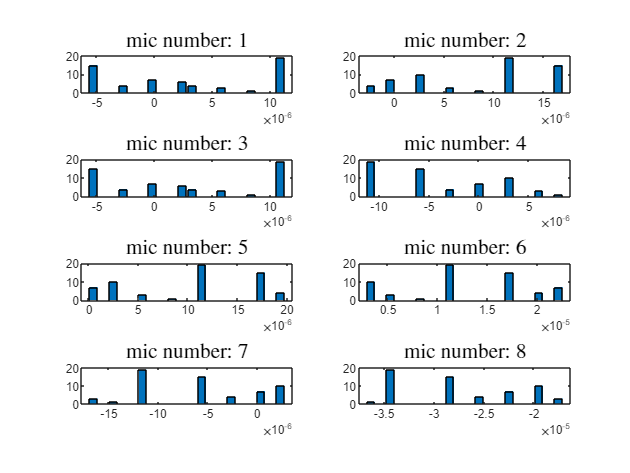

figure(1); clf;
for k = 1:size(y_toa,2)
    subplot(4,2,k);
    [N, l] = hist(meas_errors(:,k),20);
    Wb     = l(2)-l(1); % Bin widths
    Ny     = length(meas_errors(:,k)); % Nr of samples
    bar(l, N);
    title(['mic number: ',num2str(k)],'Interpreter','Latex','Fontsize',14)
end

## 2. Nonlinear least squares

load('experiment1.mat')
load('ground_truth1.mat')

### a) Nonlinear function $f$, and the noise covariance $\Sigma$

**Your text here** (*Please you the equation editor for equations)* **:**

${f\left(\theta_k \right)}_j$ represents function value at time step $k$ for $j^{\textrm{th}}$microphone.


$${f\left(\theta_k \right)}_j =\tau_k +\frac{1}{c}\sqrt{{\left(x_k -m_{x,j} \right)}^2 +{\left(y_k -m_{y,j} \right)}^2 }$$


where $f\left(\theta_k \right)={\left\lbrack {f\left(\theta_k \right)}_1 \;{f\left(\theta_k \right)}_2 \;\ldotp \ldotp \ldotp {f\left(\theta_k \right)}_8 \right\rbrack }^T$


$$\Sigma =\left\lbrack \begin{array}{cccccccc}
{\sigma^2 }_1  & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & {\sigma^2 }_2  & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & {\sigma^2 }_3  & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & {\sigma^2 }_4  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & {\sigma^2 }_5  & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & {\sigma^2 }_6  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & {\sigma^2 }_7  & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & {\sigma^2 }_8 
\end{array}\right\rbrack$$


### b) Jacobian

**Your text here** (*Please you the equation editor for equations)* **:**


$$\frac{\partial }{\partial \theta_k }f=\frac{\partial }{\partial \theta_k }\left(\tau_k +\frac{1}{c}\sqrt{{\left(x_k -m_{x,j} \right)}^2 +{\left(y_k -m_{y,j} \right)}^2 }\right)$$



$$\[ \Rightarrow \frac{\partial f}{\partial x_k} = \frac{\partial}{\partial x_k} \left( \tau_k + \frac{\sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}}{c} \right) \]
\[ = \frac{\partial}{\partial x_k} \left( \tau_k \right) + \frac{\partial}{\partial x_k} \left( \frac{\sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}}{c} \right) \]
\[ = 0 + \frac{1}{c} \cdot \frac{1}{2\sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}} \cdot 2(x_k - m_{x,j}) \]
\[ \therefore \frac{\partial f}{\partial x_k}= \frac{x_k - m_{x,j}}{c \sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}} \]$$



$$\[ \Rightarrow \frac{\partial f}{\partial y_k} = \frac{\partial}{\partial y_k} \left( \tau_k + \frac{\sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}}{c} \right) \]
\[ = 0 + \frac{1}{c} \cdot \frac{1}{2\sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}} \cdot 2(y_k - m_{y,j}) \]
\[ \therefore \frac{\partial f}{\partial y_k}  = \frac{y_k - m_{y,j}}{c \sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}} \]$$



$$\[ \Rightarrow \frac{\partial f}{\partial \tau_k} = \frac{\partial}{\partial \tau_k} \left( \tau_k + \frac{\sqrt{(x_k - m_{x,j})^2 + (y_k - m_{y,j})^2}}{c} \right) \]
\[ = 1 + 0 \]
\[ \therefore \frac{\partial f}{\partial \tau_k} = 1 \]$$



$$\Rightarrow \frac{\partial }{\partial \theta_k }f=\left\lbrack \begin{array}{ccc}
\frac{{\hat{x} }_k -m_{x,1} }{c\sqrt{{\left({\hat{x} }_k -m_{x,1} \right)}^2 +{\left({\hat{\;y} }_k -m_{y,1} \right)}^2 }} & \frac{{\hat{\;y} }_k -m_{y,1} }{c\sqrt{{\left({\hat{x} }_k -m_{x,1} \right)}^2 +{\left({\hat{\;y} }_k -m_{y,1} \right)}^2 }} & 1\\
\frac{{\hat{x} }_k -m_{x,2} }{c\sqrt{{\left({\hat{x} }_k -m_{x,2} \right)}^2 +{\left({\hat{\;y} }_k -m_{y,2} \right)}^2 }} & \frac{{\hat{\;y} }_k -m_{y,2} }{c\sqrt{{\left({\hat{x} }_k -m_{x,2} \right)}^2 +{\left({\hat{\;y} }_k -m_{y,2} \right)}^2 }} & 1\\
\ldotp  & \ldotp  & \ldotp \\
\ldotp  & \ldotp  & \ldotp \\
\frac{{\hat{x} }_k -m_{x,8} }{c\sqrt{{\left({\hat{x} }_k -m_{x,8} \right)}^2 +{\left({\hat{\;y} }_k -m_{y,8} \right)}^2 }} & \frac{{\hat{\;y} }_k -m_{y,8} }{c\sqrt{{\left({\hat{x} }_k -m_{x,8} \right)}^2 +{\left({\hat{\;y} }_k -m_{y,8} \right)}^2 }} & 1
\end{array}\right\rbrack$$



$$\therefore \frac{\partial }{\partial \theta_k }f=\left\lbrack \begin{array}{ccc}
\frac{{\hat{\;x} }_k -m_{x,1} }{c\|{\hat{\;p} }_k -m_1 {\|}_2 } & \frac{{\hat{\;y} }_k -m_{y,1} }{c\|{\hat{\;p} }_k -m_1 {\|}_2 } & 1\\
\frac{{\hat{\;x} }_k -m_{x,2} }{c\|{\hat{\;p} }_k -m_2 {\|}_2 } & \frac{{\hat{\;y} }_k -m_{y,2} }{c\|{\hat{\;p} }_k -m_2 {\|}_2 } & 1\\
\ldotp  & \ldotp  & \ldotp \\
\ldotp  & \ldotp  & \ldotp \\
\frac{{\hat{\;x} }_k -m_{x,8} }{c\|{\hat{\;p} }_k -m_8 {\|}_2 } & \frac{{\hat{\;y} }_k -m_{y,8} }{c\|{\hat{\;p} }_k -m_8 {\|}_2 } & 1
\end{array}\right\rbrack$$


### c) NLS algorithm

Implement the NLS algorithm to compute the position estimates **in the function templates** at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@f,"2a1"))

correct


disp(testmyresult(@Jacobian,"2a2"))

correct


### d) Computation of position estimates with NLS

Write your code in the box below, using the given initial state vector and maximum number of iterations.

% your code here
th0     = [0.12; 0.8; 70]; % initial state vector
maxiter = 100;             % maximum number of iterations

th_nls = [];
P_nls = [];
R = vars .* eye(8);

for k=1:size(y_toa, 1)
    yk = y_toa(k, :)' - biases';

    [th_hat, P_hat] = NLS(yk,th0,R,maxiter,mic_locations);

    th_nls = [th_nls, th_hat];
    P_nls = cat(3, P_nls, P_hat);

end

### e) Visualisation and interpretation

Uncomment the code below.

**Your text here****:**

Although the mean estimated position never precisely aligns with the ground truth, the path is consistently followed. Furthermore, at each time step, the uncertainty of the estimate intersects with the ground truth. The ellipsoid's shape indicates a small variance in the direction of movement and a high variance in its perpendicular direction. Additionally, when only one direction is changing, the variance reduces. This is more evident at curvatures, where the major axis of the ellipsoid elongates further than during horizontal or vertical movements.

Moreover, in Figure 2 of the assignment questions report, a high likelihood $\left.\log \left(p\left(y_k \right|p_k \right)\right)$ of the measurements at three locations is illustrated by yellow in the colour map. The shape of the log-likelihood is influenced by the spread of the likelihood function. This spread is related to the uncertainty in the parameter estimates, which is represented by the covariance matrix. This is apparent in each plot, as the shape of the log-likelihood is similar to the depicted ellipsoids in their respective location regions on the board.

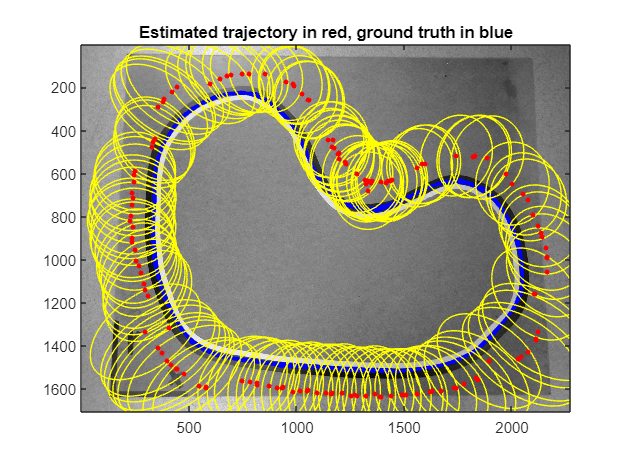

figure(2); clf;
plotresults(th_nls(1:2,:),P_nls(1:2,1:2,:),mic_locations',ground_truth);

## 3. Kalman filtering 

### a) KF algorithm

Implement the Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_kf,"3a1"))

correct


disp(testmyresult(@timeupdate_kf,"3a2"))

correct


### b) Computation of position estimates with KF

Write your code in the box below, using the given initial position and intial covariance matrix.

Tune $Q$ and $R_k$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

The measurement noise covariance matrix, $R_k$, is chosen as the NLS covariance matrix $P_{\textrm{NLS}}$ computed in the previous exercise, given that the pseudo-measurements $y_k$ are chosen from the position estimates of the previous exercise. Thus, $R_k$ is kept constant, while the process noise covariance matrix $Q$, was tuned to align the mean of the filtered distribution as closely as possible with the ground truth.

Initially, $Q$ is chosen as an identity matrix to ensure equal variances in the x and y positions with no cross-covariance between the different directions, since a variation in one direction does not influence the other. As the elements of $R_k$ are in the ${10}^{-6}$ scale, $Q$ is tuned with the same scaling to achieve a balance between the actual measurements and the predictions based on system dynamics. The Kalman filter combines these two sources of information based on the relative covariance values. If one information source has very high confidence (low covariance values) relative to the other information source, then the information from the low confidence source is insignificant. The magnitude of the variances of $Q$ is adjusted iteratively by comparing the mean filtered distribution with the ground truth from the resulting plot. 

% your code here

p_0 = [th0(1); th0(2)];
P_0 = 10^4*eye(2);
R = P_nls;
Q = (0.4*10^-6)*eye(2);
y = th_nls;

[p_kf,P_kf] = KF(p_0,P_0,R,Q,y);

### c) Visualisation

Plot the mean and covariance of the **filtered** distribution. Uncomment the plot below.

**Your text here:**

The mean of the filtered distribution is closer to the ground truth compared to the NLS estimate. This improvement is due to the inclusion of system dynamics in the Kalman filter, which factors in both the dynamic model and the measurement model in its estimate. Moreover, the covariance of the filtered distribution is significantly smaller than that of the NLS estimate. These improved results were obtained from the ability to tune $Q$ with the ground truth, which is not possible in the NLS algorithm.

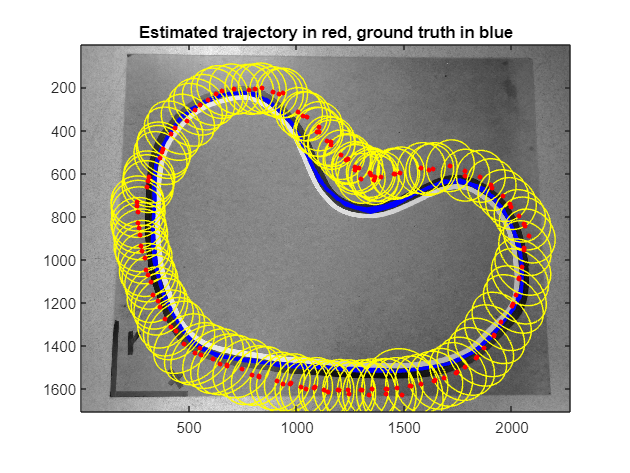

figure(3); clf;
plotresults(p_kf,P_kf,mic_locations',ground_truth);

## 4. Extended Kalman fitering

### a) EKF algorithm

Implement the extended Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check wheather your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_ekf,"4a1"))

correct


disp(testmyresult(@timeupdate_ekf,"4a2"))

correct


### b) Computation of position estimates with EKF

Tune $Q$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

The $R$ matrix was chosen as the measurement noise covariance matrix determined from the calibration process because the TOA measurements are used as the measurement model. In this case, the dynamic model has three states, so $Q$ is a 3x3 diagonal matrix. The additional element is the variance of the time of sound emission, which was calculated from the TOA measuments given for calibration.

$R$ is kept constant while $Q$ is tuned similarly to the process described for the Kalman Filter. The cross-covariance between the different states is set to zero since a movement in one direction does not influence the other. Additionally, the time of sound emission is periodic, making it independent of the current position of the robot. Initially, the magnitudes of the variances in the $Q$ matrix were large compared to the $R$ matrix, to observe the filtering influenced mainly by the measurement model. This resulted in a path similar to what is observed in the NLS trajectory. Consequently, the variances were reduced to rely further on the dynamic model. This was done iteratively until the mean of the filtered distribution closely follows the ground truth. If the variances were further reduced, bringing it closer to the $R$ matrix in magnitude, the trajectory starts to drift away from the ground truth. Thus, the $Q$ matrix is relatively larger than the $R$ matrix. This led to the conclusion that the measurement update is significantly more accurate than the time update. Hence, there is more confidence in the measurements rather than the given dynamic model.

% your code here

R = vars .* eye(8);
Q = diag([0.45*10^-6, 0.7*10^-6, (mean(std(diff(y_toa))))^2]);
P_0 = 10^4 * eye(3);
y = y_toa - biases;

[th_ekf,P_ekf] = EKF(th0,P_0,y,mic_locations,R,Q);


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution.

**Your text here:**

The trajectory obtained with the Extended Kalman filter is very similar to the Kalman-filtered trajectory. The primary difference between the two lies in the convergence of the initial estimates toward the ground truth. While the Extended Kalman-filtered distribution converged in three steps, the Kalman-filtered distribution achieved convergence in the first step. This discrepancy arises from the pre-processing step of the Kalman filter, which utilized reliable filtered measurements obtained from the NLS. One hundred iterations were computed to refine the initial position estimate from the center of the board to the ground truth. In contrast, the Extended Kalman filter used calibrated measurements, and the path converged to the ground truth through a combined measurement and time update at each step. This leads to the conclusion that the Extended Kalman filter yields trajectories equivalent to the combined NLS algorithm and Kalman filter.

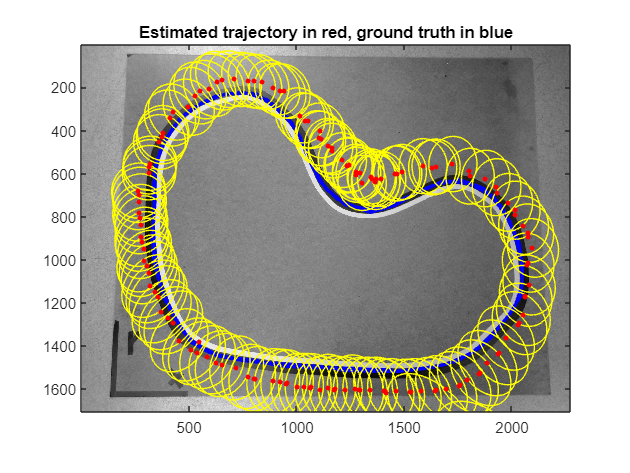

figure(4); clf;
plotresults(th_ekf(1:2,:),P_ekf(1:2,1:2,:),mic_locations',ground_truth);

# Copy all your functions below this text before exporting to PDF!! 

## Functions

NLS

function ftheta = f(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % ftheta            evaluation of f at current state estimate
    
    c      = 343; % in [m/s]
    pos_prev_est = [theta(1) .* ones(8, 1), theta(2) .* ones(8, 1)];
    Tau_prev_est = theta(3) .* ones(8, 1);
    
    ftheta = Tau_prev_est + (sqrt(sum((pos_prev_est - mic_locations).^2,2)))/c;

end

function dF = Jacobian(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % dF                evaluation of Jacobian at current state estimate
    
    c = 343; % in [m/s]
    
    pos_prev_est = [theta(1) .* ones(8, 1), theta(2) .* ones(8, 1)];
    dF = [((pos_prev_est(:, 1) - mic_locations(:,1)) ./ (c*sqrt(sum((pos_prev_est - mic_locations).^2,2)))), ((pos_prev_est(:,2) - mic_locations(:,2)) ./ (c*sqrt(sum((pos_prev_est - mic_locations).^2,2)))), ones(8, 1)];
    
end

function [th_hat, P_hat] = NLS(yk,th_hat0,R,maxiter,mic_locations)
    % INPUT: 
    % y_k               kth measurement
    % th_hat0           initial estimate
    % R                 covariance matrix of measurement noise
    % maxiter           maximum number of iterations 
    % mic_locations     microphone locations

    % OUTPUT    
    % th_hat            mean of kth NLS estimate
    % P_hat             covariance matrix of kth NLS estimate

    th_hat = th_hat0;
    
    for i=1:maxiter

        F_k = Jacobian(th_hat, mic_locations);

        error_k = yk - f(th_hat, mic_locations);

        theta_delta_est = (F_k' * (R \ F_k)) \ F_k' * (R \ error_k);

        th_hat = th_hat + theta_delta_est;

   end

    P_hat = inv((F_k' * (R \ F_k)));

end

KF

function [p_kf,P_kf] = measupdate_kf(p_k,P_k,R_k,y_k)
    % INPUT
    % p_k   mean of predictive distribution for k|k-1
    % P_k   covariance of predictive distribution for k|k-1
    % R_k   kth measurement noise covariance matrix
    % y_k   kth measurment
    % OUTPUT
    % p_kf  mean of filtering distribution for k|k
    % p_kf  covariance matrix of filtering distribution for k|k

    % Measurement update
    C = eye(2);
    K = P_k * C'  / (C * P_k * C'  + R_k);

    p_kf = p_k + K * (y_k - C * p_k); 
    P_kf = P_k - P_k * C' / (C * P_k * C' + R_k) * C * P_k;

end

function [p_kk,P_kk] = timeupdate_kf(p_k,P_k,Q)
    % INPUT
    % p_k   mean of filtering distribution for k|k
    % P_k   covariance matrix of filtering distribution for k|k
    % Q     process noise covariance matrix
    % OUTPUT
    % p_kk  mean of predictive distribution for k+1|k
    % P_kk  covariance of predictive distribution for k+1|k

    A = eye(2);

    % Times update
    p_kk = A * p_k;
    P_kk = A * P_k * A' + Q;

end

function [p_kf,P_kf] = KF(p_0,P_0,R,Q,y)
    % INPUT: 
    % p_0       prior mean
    % P_0       prior covariance matrix
    % R         Measurement noise covariance matrices for k = 1,...,137
    % Q         Process noise covariance matrix
    % y         Measurements for k = 1,...,137
    % OUTPUT    
    % p_kf      Mean of the filtered distribution for every k
    % P_kf      Covariance matrix of the filtered distribution for every k

    p_k = p_0;
    P_k = P_0;

    p_kf = [];
    P_kf = [];

    for k=1:size(y, 2)

        R_k = R(1:2, 1:2, k);

        y_k = y(1:2, k);

        [p_k,P_k] = measupdate_kf(p_k,P_k,R_k,y_k);

        P_kf = cat(3, P_kf, P_k);
        p_kf = [p_kf, p_k];

        [p_k,P_k] = timeupdate_kf(p_k,P_k,Q);

    end

end

EKF

function [th_ekf,P_ekf] = measupdate_ekf(th_k,P_k,y_k,mic_locations,R)
    % INPUT
    % th_k              mean of predictive distribution for k|k-1
    % P_k               covariance of predictive distribution for k|k-1
    % y_k               kth measurment
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % OUTPUT
    % th_ekf            mean of filtering distribution for k|k
    % p_ekf             covariance matrix of filtering distribution for k|k

    c               = 343; %In meters per second

    dF = Jacobian(th_k,mic_locations);

    error_k = y_k - f(th_k, mic_locations);

    K = P_k * dF'  / (dF * P_k * dF'  + R);

    th_ekf = th_k + K * error_k;

    P_ekf = P_k - (P_k * dF' / (dF * P_k * dF' + R)) * dF * P_k;

end

function [th_kk,P_kk] = timeupdate_ekf(th_k,P_k,Q)
    % INPUT
    % th_k   mean of filtering distribution for k|k
    % P_k    covariance matrix of filtering distribution for k|k
    % Q      process noise covariance matrix
    % OUTPUT
    % th_kk  mean of predictive distribution for k+1|k
    % P_kk   covariance of predicted distribution for k+1|k
    
    delta_Tau = 0.5115; % mean(diff(y_toa(:,1)));
    
    A = eye(3);
    B = [0; 0 ; delta_Tau];
    th_kk = A * th_k + B;

    P_kk = A * P_k * A' + Q;

end

function [th_ekf,P_ekf] = EKF(th_0,P_0,y,mic_locations,R,Q)
    % INPUT 
    % th_0              prior mean
    % P_0               prior covariance matrix
    % y                 measurements for k = 1,...,137
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % Q                 process noise covariance matrix
        
    % OUTPUT    
    % th_ekf            mean of the filtering distribution for every k
    % P_ekf             covariance matrix of the filtering distribution for every k  

    th_ekf = [];
    P_ekf = [];

    th_kk = th_0;
    P_kk = P_0;
    
    for k = 1:size(y, 1)
    
        y_k = y(k,:)';
        [th_k,P_k] = measupdate_ekf(th_kk,P_kk,y_k,mic_locations,R);

        P_ekf = cat(3, P_ekf, P_k);
        th_ekf = [th_ekf, th_k];

        [th_kk,P_kk] = timeupdate_ekf(th_k,P_k,Q);
    
    
    end
   
end
